wi0 = FTtest(0);

'FTtest' is not found in the current folder or on the MATLAB path, but exists in:
    /home/dmf/Documents/MATLAB/HVGtest

Change the MATLAB current folder or add its folder to the MATLAB path.

[tsrow,tscol] = size(wi0);
wimin = zeros(tsrow,tscol);
wimax = zeros(tsrow,tscol);
wis = zeros(tsrow,tscol,19);
for i = 1:19
    wis(:,:,i) = FTtest('FT')
end
for j = 1:tsrow
    for k = tscol
        wimin(j,k) = min(wis(j,k,:));
        wimax(j,k) = max(wis(j,k,:));
    end
end


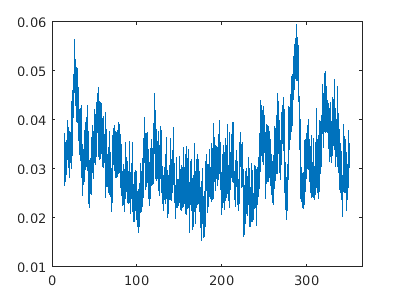


x = [1+wlen:8760-wlen]/24;
plot(x,wi(:,6))
xlim([0 365])

tl = tiledlayout(2,3);
wlen = 0;
rn = 0;
t = (wlen+1+rn:8784-wlen-rn)/24;
yl = ["AEO","AEO","AEO","IMI","IMI","IMI"];
tts = ["PM2.5-NO2","PM2.5-O3","NO2-O3","PM2.5-NO2","PM2.5-O3","NO2-O3"];
ord = [1 3 5 2 4 6];
for ind = 1:6
    nexttile
    original = running_mean(bj2016wi(:,ord(ind)),rn);
    upper = running_mean(wimax(:,3*ind-2),rn);
    lower = running_mean(wimin(:,3*ind-2),rn);
    plot(t,original)%,t,upper,t,lower)
    %     errorbar(1:20,bj2016wimean(:,ind),bj2016wistd(:,ind))
    xlim([0 367])
    %     xlim([0 21])
    %     xlabel('sampling interval(hour)')
    ylabel(yl(ind))
    title(tts(ind))
    %     legend(["original","upper","lower"])
    %     legend(["original","highpass","lowpass"])
end
tl.TileSpacing = 'compact';
tl.Padding = 'compact';